clc;
clear;
warning('off','all')
toggle_savefig = 0;

test_data = readtable('test_data.csv', 'NumHeaderLines',0)

test_data = 266814×12 table
    Latitude    Longitude       Time        MWP       MWD        SWH        U10        V10       Accident    Wind_Speed    Wind_Direction    Predicted_Cluster
    ________    _________    __________    ______    ______    _______    _______    ________    ________    __________    ______________    _________________

        40          120      2024-01-01    3.9761    227.17    0.72152      4.239      2.0862       0          4.7246          26.204                3        
        40        120.5      2024-01-01    4.2949    233.78     1.0882      7.282      4.0706       0          8.3425          29.205                0        
        40          121      2024-01-01     4.529     241.1     1.3304     8.4968      4.1878       0          9.4728          26.237                0        
        40        121.5      2024-01-01     4.585    247.43     1.1109      6.032      4.1839       0           7.341          34.746                0        
        40       

cluster_accident_ratio = readtable('cluster_accident_ratio.csv', 'NumHeaderLines', 0)

cluster_accident_ratio = 13×2 table
    Cluster     Accident 
    _______    __________

       0       2.2196e-05
       1       5.2994e-05
       2       3.3543e-05
       3       4.2788e-05
       4       1.8454e-05
       5       2.5899e-05
       6       1.0138e-05
       7       5.6313e-05
       8                0
       9                0
      10       1.8481e-05
      11       2.3643e-05
      12        2.478e-05


% Accidentが1のデータを抽出
accident_indices = test_data.Accident == 1;
accident_data = test_data(accident_indices, :);
% 同時刻のデータを抽出
unique_times = unique(accident_data.Time);

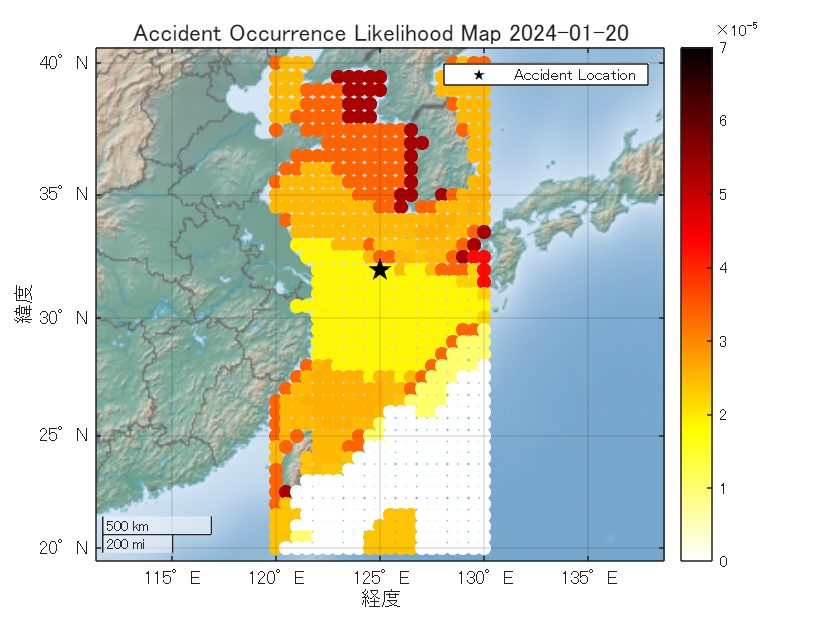

unique_time1 = unique_times(1); % 2024-01-20
map_data = test_data(ismember(test_data.Time, unique_time1), :);

% クラスタに基づく色を計算
probabilities = zeros(height(map_data), 1);
for i = 1:height(map_data)
    cluster_id = map_data.Predicted_Cluster(i);
    prob = cluster_accident_ratio.Accident(cluster_accident_ratio.Cluster == cluster_id);
    probabilities(i) = prob;
end

% クラスタ―7と予測されているデータを抽出
abnormal_area = map_data(map_data.Predicted_Cluster == 7, :);

% 地図にプロット
figure;
geobasemap('colorterrain')
hold on;
scatter(map_data.Latitude, map_data.Longitude, 50, probabilities, 'filled');
caxis([0, 7e-5]);
colormap(gca, flipud(hot));
colorbar;

% アクシデントの場所をプロット（星マーカー）
scatter(accident_data.Latitude(1), accident_data.Longitude(1), 150, 'k', 'p', 'filled', 'DisplayName', 'Accident Location'); 

% 異常海域（クラス7）を網掛けで表示
scatter(abnormal_area.Latitude, abnormal_area.Longitude, 80, 'k', 'x');

title(['Accident Occurrence Likelihood Map ', datestr(unique_time1, 'yyyy-mm-dd')], FontSize=12)
legend('','Accident Location');
hold off;
exportgraphics(gcf, ['Accident_Likelihood_Map_', datestr(unique_time1, 'yyyy-mm-dd'), '.png']);

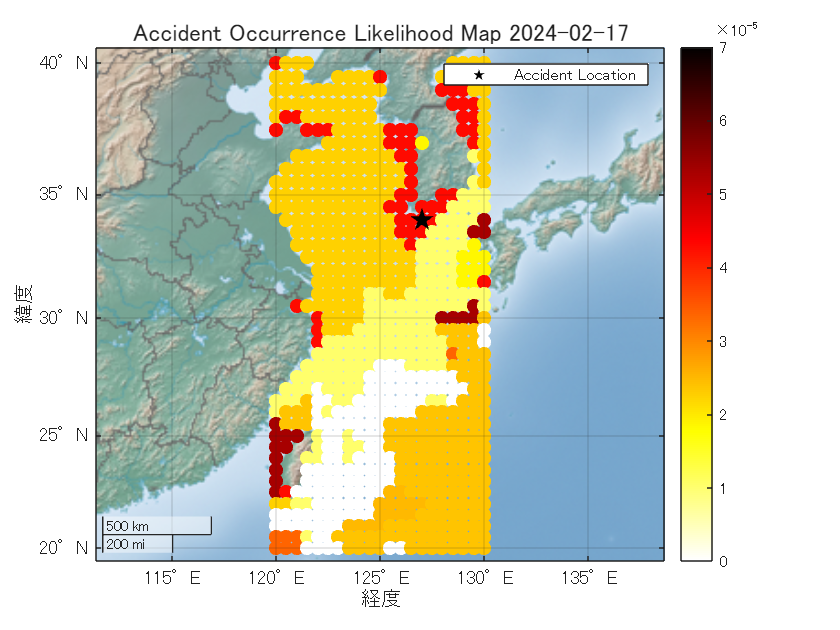

unique_time2 = unique_times(2); % 2024-02-17
map_data = test_data(ismember(test_data.Time, unique_time2), :);

% クラスタに基づく色を計算
probabilities = zeros(height(map_data), 1);
for i = 1:height(map_data)
    cluster_id = map_data.Predicted_Cluster(i);
    prob = cluster_accident_ratio.Accident(cluster_accident_ratio.Cluster == cluster_id);
    probabilities(i) = prob;
end

% クラスタ―7と予測されているデータを抽出
abnormal_area = map_data(map_data.Predicted_Cluster == 7, :);

% 地図にプロット
figure;
geobasemap('colorterrain');
hold on;
scatter(map_data.Latitude, map_data.Longitude, 50, probabilities, 'filled');
caxis([0, 7e-5]);
colormap(gca, flipud(hot));
colorbar;

% アクシデントの場所をプロット（星マーカー）
scatter(accident_data.Latitude(2), accident_data.Longitude(2), 150, 'k', 'p', 'filled', 'DisplayName', 'Accident'); 

% 異常海域（クラス7）を網掛けで表示
scatter(abnormal_area.Latitude, abnormal_area.Longitude, 80, 'k', 'x');

title(['Accident Occurrence Likelihood Map ', datestr(unique_time2, 'yyyy-mm-dd')], FontSize=12)
legend('','Accident Location');
hold off;
exportgraphics(gcf, ['Accident_Likelihood_Map_', datestr(unique_time2, 'yyyy-mm-dd'), '.png']);